# **Projeto - Estabilização de um duplo pêndulo invertido**

%%
clc;close all; clear all;
format bank;
%%

## ** Modelagem do Sistema**

%% Parâmetros do sistema
m = 1;     %kilograma
m1 = 1;   % kilograma
m2 = 1;    % kilograma
l1 = 0.05; % metros
l2 = 0.05; % metros
g = 9.81;  % m/s^2
f0 = 0.01;
f1 = 0.007;
f2 = 0.007;
J1 = 0.00083;
J2 = 0.00083;

% Simplificação (Obtido por sympy - python)
A01 =J1*J2*(m+m1+m2)+J1*l2*l2*m2*(m + m1)+J2*l1*l1*(m*m1+4*m*m2+m1*m2);
A02 = m*l1*l1*l2*l2*m1*m2;
A0 = A01 + A02;

A1 = g*l1*(m1+2*m2);
A2 = g*l2*m2;

A3 = -J2*l1*(m1+2*m2)-l1*l2*l2*m1*m2;
A4 = J2*(m+m1+m2)+m*l2*l2*m2 + l2*l2*m1*m2;
A5 = -l1*l2*m2*(2*m+m1);

A6 = -l2*m2*(J1-l1*l1*m1);
A7 = -l1*l2*m2*(2*m+m1);
A8 = J1*(m+m1+m2)+l1*l1*m2*(m*m1 +4*m +m1);

B1 = J1*(J2 +l2*l2*m2) + J2*(l1*l1*m1+4*l1*l1*m2)+l1*l1*l2*l2*m1*m2;
B2 = -J2*l1*m1-2*J2*l1*m2-l1*l2*l2*m1*m2;
B3 = -J1*l2*m2+l1*l1*l2*m1*m2;

% Definindo as Matrizes no tempo contínuo
Ac = [0 0 0 1 0 0
     0 0 0 0 1 0
     0 0 0 0 0 1
     0 -(A1*A3)/A0 -(A2*A6)/A0 0 0 0
     0 -(A1*A4)/A0 -(A2*A7)/A0 0 0 0
     0 -(A1*A5)/A0 -(A2*A8)/A0 0 0 0
    ];

Bc = [0
     0
     0
     B1/A0
     B2/A0
     B3/A0];

Cc = eye(6);

Dc = zeros(size(Cc,1),size(Bc,2));

estados = {'x' 'phi_1' 'phi_2' 'dx' 'dph1' 'dphi2'};
estados_estimados = {'x_{hat}' 'phi_1_{hat}' 'phi_2_{hat}' 'dx_{hat}' 'dphi_1_{hat}' 'dphi_2_{hat}'};
entradas = {'u'};
saidas = estados;
saidas_estimadas = estados_estimados;

% Definindo o sistema no tempo continuo
sys_c = ss(Ac, Bc,Cc, Dc, 'statename', estados, ...
    'inputname', entradas,...
    'outputname', saidas)

sys_c =
 
  A = 
               x   phi_1   phi_2      dx    dph1   dphi2
   x           0       0       0       1       0       0
   phi_1       0       0       0       0       1       0
   phi_2       0       0       0       0       0       1
   dx          0   14.73  -1.644       0       0       0
   dph1        0  -442.3   147.6       0       0       0
   dphi2       0   442.9  -344.3       0       0       0
 
  B = 
               u
   x           0
   phi_1       0
   phi_2       0
   dx     0.7781
   dph1   -10.01
   dphi2   3.351
 
  C = 
              x  phi_1  phi_2     dx   dph1  dphi2
   x          1      0      0      0      0      0
   phi_1      0      1      0      0      0      0
   phi_2      0      0      1      0      0      0
   dx         0      0      0      1      0      0
   dph1       0      0      0      0      1      0
   dphi2      0      0      0      0      0      1
 
  D = 
          u
   x      0
   phi_1  0
   phi_2  0
   dx     0
   dph1   0
   dphi2 

% Modelo no Tempo Discreto
% Período de Amostragem
Ts = 0.01; %(1/0.01) = 100 Hz frequência de amostragem

sys_d = c2d(sys_c,Ts,'zoh') % zero-order hold

sys_d =
 
  A = 
                   x       phi_1       phi_2          dx        dph1       dphi2
   x               1   0.0007337  -8.105e-05        0.01    2.45e-06  -2.717e-07
   phi_1           0       0.978    0.007334           0    0.009926   2.451e-05
   phi_2           0       0.022      0.9829           0   7.353e-05    0.009943
   dx              0      0.1461    -0.01598           1   0.0007337  -8.105e-05
   dph1            0       -4.38       1.457           0       0.978    0.007334
   dphi2           0       4.371      -3.412           0       0.022      0.9829
 
  B = 
                   u
   x       3.884e-05
   phi_1  -0.0004986
   phi_2   0.0001652
   dx       0.007756
   dph1     -0.09932
   dphi2     0.03258
 
  C = 
              x  phi_1  phi_2     dx   dph1  dphi2
   x          1      0      0      0      0      0
   phi_1      0      1      0      0      0      0
   phi_2      0      0      1      0      0      0
   dx         0      0      0      1      0    

% Obtendo as matrizes discretas A,B,C e D
Ad = sys_d.A;
Bd = sys_d.B;
Cd = sys_d.C;
Dd = sys_d.D;


### Estabilidade

% Auto valores sistema contínuo
auto_valores_c = eig(sys_c)

auto_valores_c =           0.00
          0.00
          0.00
          0.00
          0.00
          0.00



% Auto valores sistema discreto
auto_valores_d = eig(sys_d)

auto_valores_d =           1.00
          1.00
          0.97
          0.97
          0.99
          0.99


### Controlabilidade e Observabilidade

% Controlabilidade
matriz_controlabilidade = ctrb(Ad,Bd)

matriz_controlabilidade =           0.00          0.00          0.00          0.00          0.00          0.00
         -0.00         -0.00         -0.00         -0.00         -0.00         -0.00
          0.00          0.00          0.00          0.00          0.00          0.00
          0.01          0.01          0.01          0.01          0.01          0.01
         -0.10         -0.09         -0.09         -0.07         -0.06         -0.04
          0.03          0.03          0.02          0.00         -0.02         -0.04



[linhas, colunas]=size(matriz_controlabilidade);
if rank(matriz_controlabilidade) == colunas
    rank_matriz_controlabilidade = rank(matriz_controlabilidade)
    disp('Controlável')
end

rank_matriz_controlabilidade =           6.00


Controlável



% Observabilidade
matriz_observabilidade = obsv(Ad,Cd)

matriz_observabilidade =           1.00             0             0             0             0             0
             0          1.00             0             0             0             0
             0             0          1.00             0             0             0
             0             0             0          1.00             0             0
             0             0             0             0          1.00             0
             0             0             0             0             0          1.00
          1.00          0.00         -0.00          0.01          0.00         -0.00
             0          0.98          0.01             0          0.01          0.00
             0          0.02          0.98             0          0.00          0.01
             0          0.15         -0.02          1.00          0.00         -0.00



if rank(matriz_observabilidade) == colunas
    rank_matriz_observabilidade = rank(matriz_observabilidade)
    disp('Observável')
end

rank_matriz_observabilidade =           6.00


Observável


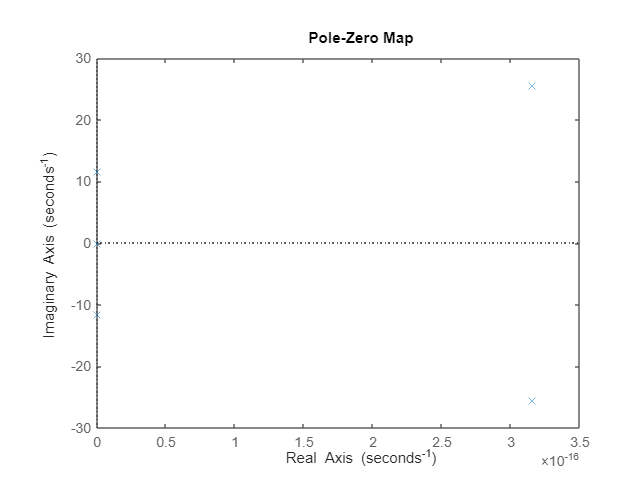


% Estabilidade
figure;
pzmap(sys_c)

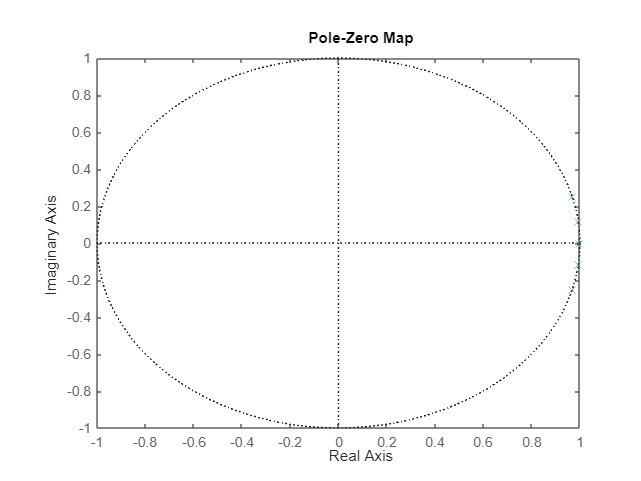

pzmap(sys_d)

## Análise de Malha Aberta

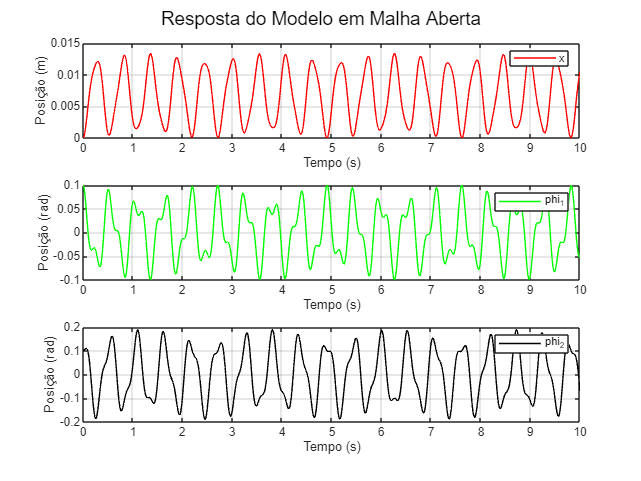


% Simulando
tp = 0:Ts:10; % tempo de simulação

x0 = [0 0.1 0.1 0 0 0]; % Condições iniciais

u = zeros(size(tp)); % Entrada de controle

% Simula o sistema linear original dado pela planta

[y_ma,t,x_ma] = lsim(sys_d,u,tp,x0); % Malha aberta
%[y_ma,t,x_ma] = impulse(sys_d); % Malha aberta

% Plotando
figure;

subplot(3,1,1);
plot(t,y_ma(:,1),'r','LineWidth',1)
xlim([0 10]);
legend(estados{1});
xlabel('Tempo (s)');
ylabel('Posição (m)');
grid on;

subplot(3,1,2);
plot(t,y_ma(:,2),'g','LineWidth',1)
xlim([0 10]);
legend(estados{2});
xlabel('Tempo (s)');
ylabel('Posição (rad)');
grid on;

subplot(3,1,3);
plot(t,y_ma(:,3),'k','LineWidth',1)
xlim([0 10]);
legend(estados{3});
xlabel('Tempo (s)');
ylabel('Posição (rad)');
grid on;

sgtitle('Resposta do Modelo em Malha Aberta');

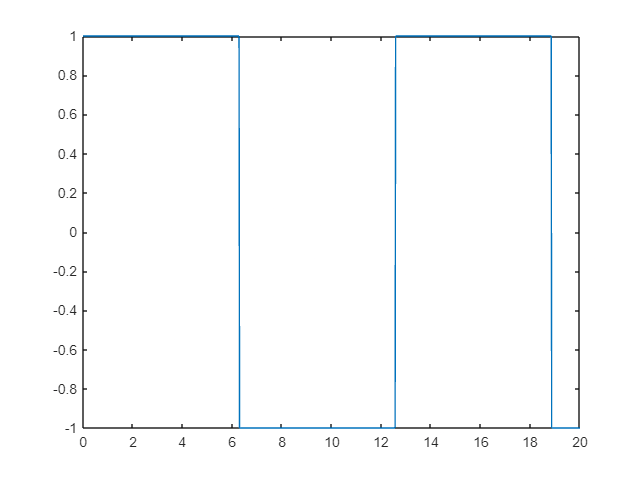

onda_quadrada = square(t);
figure;
plot(2*t,onda_quadrada)

## Controaldor LQR - Malha fechada

% PROJETO DE CONTROLADOR LQR NA PLANTA ORIGINAL

% Definindo as matrizes de peso Q e R:
Q_lqr =[50 0 0 0 0 0; % Penaliza os estados
      0 10 0 0 0 0;
      0 0 20 0 0 0;
      0 0 0 0 0 0;
      0 0 0 0 0 0;
      0 0 0 0 0 0];
R_lqr = 0.01;    % Penaliza o esforço de controle
x0_lqr = [0.1 -0.1 0.1 0 0 0]; % Condições iniciais

% Calcula os ganhos K dos estados:
K_lqr = dlqr(Ad, Bd, Q_lqr, R_lqr)

K_lqr =          58.84        -47.28          5.87         29.15         -1.45         -1.11



% Cria sistema em malha fechada: Ac = Ad - Bd*K_lqr
A_mf_lqr = Ad - Bd*K_lqr;
B_mf_lqr = Bd;
C_mf_lqr = eye(6);
D_mf_lqr = Dd;

% Rastreamento de trajetoria
k1 = K_lqr(1)

k1 =          58.84


B_mf_lqr_r = Bd*k1

B_mf_lqr_r =           0.00
         -0.03
          0.01
          0.46
         -5.84
          1.92



% sem restreamento de x
sys_mf_lqr = ss(A_mf_lqr, B_mf_lqr, C_mf_lqr, D_mf_lqr, Ts);

% Com rastreamento de x
sys_mf_lqr_r = ss(A_mf_lqr, B_mf_lqr_r, C_mf_lqr, D_mf_lqr, Ts);


### Resposta Inicial

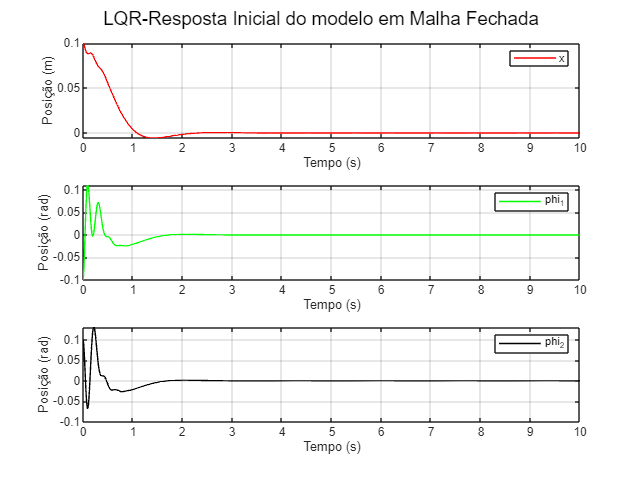

% Calcula resposta inicial do sistema em MF com LQR
[y_lqr_i, t, x_lqr_i] = initial(sys_mf_lqr,x0_lqr,tp);

% Plotar a resposta do sistema
figure;

subplot(3,1,1);
plot(t,y_lqr_i(:,1),'r','LineWidth',1)
legend(estados{1});
xlabel('Tempo (s)');
ylabel('Posição (m)');
grid on;

subplot(3,1,2);
plot(t,y_lqr_i(:,2),'g','LineWidth',1)
legend(estados{2});
xlabel('Tempo (s)');
ylabel('Posição (rad)');
grid on;

subplot(3,1,3);
plot(t,y_lqr_i(:,3),'k','LineWidth',1)
legend(estados{3});
xlabel('Tempo (s)');
ylabel('Posição (rad)');
grid on;

sgtitle('LQR-Resposta Inicial do modelo em Malha Fechada');

### Resposta ao Degrau

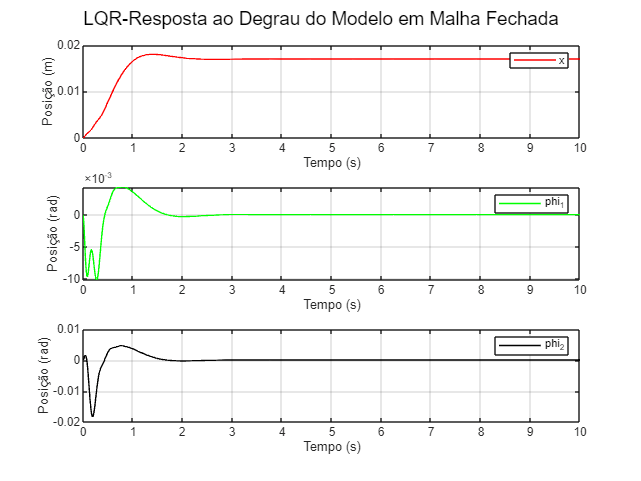

% Calcula resposta ao degrau do sistema em MF com LQR
[y_lqr_s, t, x_lqr_s] = step(sys_mf_lqr,10);

% Plotar a resposta do sistema
figure;

subplot(3,1,1);
plot(t,y_lqr_s(:,1),'r','LineWidth',1)
legend(estados{1});
xlabel('Tempo (s)');
ylabel('Posição (m)');
grid on;

subplot(3,1,2);
plot(t,y_lqr_s(:,2),'g','LineWidth',1)
legend(estados{2});
xlabel('Tempo (s)');
ylabel('Posição (rad)');
grid on;

subplot(3,1,3);
plot(t,y_lqr_s(:,3),'k','LineWidth',1)
legend(estados{3});
xlabel('Tempo (s)');
ylabel('Posição (rad)');
grid on;

sgtitle('LQR-Resposta ao Degrau do Modelo em Malha Fechada');

rastreamento

entrada_r =  2*square(t)

entrada_r =           2.00
          2.00
          2.00
          2.00
          2.00
          2.00
          2.00
          2.00
          2.00
          2.00


entrada_r1 = 0.25*sawtooth(t,1/2)

entrada_r1 =          -0.25
         -0.25
         -0.25
         -0.25
         -0.24
         -0.24
         -0.24
         -0.24
         -0.24
         -0.24


[y_lqr_rs, t, x_lqr_rs] = step(sys_mf_lqr_r,10);
%[y_lqr_rs, t, x_lqr_rs] = lsim(sys_mf_lqr_r,entrada_r1,t);
figure;
plot(t,y_lqr_rs(:,1),'LineWidth',1)
legend('X','U');

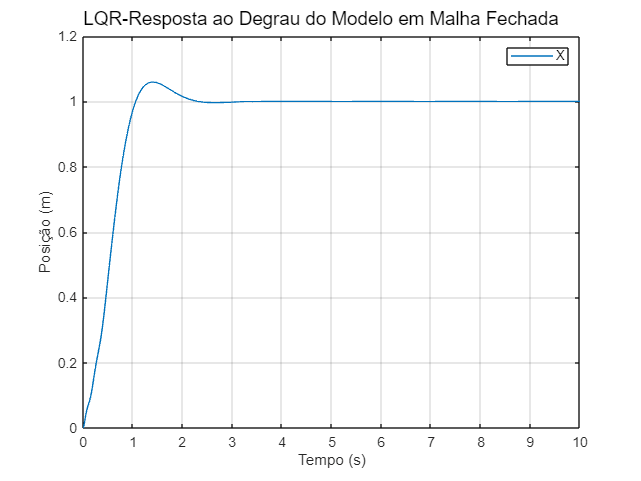

xlabel('Tempo (s)');
ylabel('Posição (m)');
grid on;
sgtitle('LQR-Resposta ao Degrau do Modelo em Malha Fechada');

### Resposta ao Impulso

% Calcula resposta ao impulsi do sistema em MF com LQR
[y_lqr_ip,t, x_lqr_ip] = impulse(sys_mf_lqr)

y_lqr_ip =              0             0             0             0             0             0
          0.00         -0.05          0.02          0.78         -9.93          3.26
          0.01         -0.13          0.04          0.48         -5.86          1.53
          0.01         -0.17          0.05          0.24         -2.34         -0.23
          0.02         -0.18          0.04          0.06          0.50         -1.83
          0.02         -0.16          0.01         -0.06          2.57         -3.11
          0.01         -0.13         -0.02         -0.14          3.88         -3.98
          0.01         -0.09         -0.07         -0.17          4.47         -4.37
          0.01         -0.04         -0.11         -0.16          4.45         -4.31
          0.01         -0.00         -0.15         -0.13          3.94         -3.82


t =              0
          0.01
          0.02
          0.03
          0.04
          0.05
          0.06
          0.07
          0.08
          0.09


x_lqr_ip =              0             0             0             0             0             0
          0.00         -0.05          0.02          0.78         -9.93          3.26
          0.01         -0.13          0.04          0.48         -5.86          1.53
          0.01         -0.17          0.05          0.24         -2.34         -0.23
          0.02         -0.18          0.04          0.06          0.50         -1.83
          0.02         -0.16          0.01         -0.06          2.57         -3.11
          0.01         -0.13         -0.02         -0.14          3.88         -3.98
          0.01         -0.09         -0.07         -0.17          4.47         -4.37
          0.01         -0.04         -0.11         -0.16          4.45         -4.31
          0.01         -0.00         -0.15         -0.13          3.94         -3.82


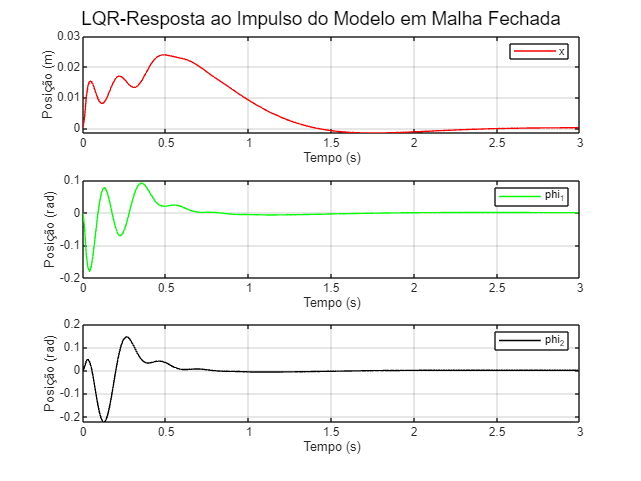



% Plotar a resposta do sistema
figure;

subplot(3,1,1);
plot(t,y_lqr_ip(:,1),'r','LineWidth',1)
legend(estados{1});
xlabel('Tempo (s)');
ylabel('Posição (m)');
grid on;

subplot(3,1,2);
plot(t,y_lqr_ip(:,2),'g','LineWidth',1)
legend(estados{2});
xlabel('Tempo (s)');
ylabel('Posição (rad)');
grid on;

subplot(3,1,3);
plot(t,y_lqr_ip(:,3),'k','LineWidth',1)
legend(estados{3});
xlabel('Tempo (s)');
ylabel('Posição (rad)');
grid on;

sgtitle('LQR-Resposta ao Impulso do Modelo em Malha Fechada');

## Estimador de estados otimo: Filtro de Kalman

%% Desenho do Observador
% Parametros de G e H
G = Cc; % because 6 states so 6 disturbances (p =n) 
H = zeros(6,6); % 6 outputs so 0 matrix of 6x6

% Matrizes de Covariancia, process Q, measurement R
Qcov = diag(1e-7*ones(1,6)); % Q is 6x6
Rcov = diag(1e-3*ones(1,6)); % R is 6x6

% Sistema com pertubações
sys_kf = ss(Ad, [Bd G] ,Cd, [Dd H],Ts, 'statename', estados_estimados, ...
    'inputname', entradas,...
    'outputname', saidas_estimadas);


% Obtem L e P, assumindo que w e v não estão correlacionados L
% Isso significa que N = 0 no ultimo parametro
[kest, L, P] = kalman(sys_kf, Qcov, Rcov);

% Checa o valor de L que o Matlab retorna:
L_bar = (Ad*P*Cd)/(Cd * P * Cd' +Rcov);

% Verifica o erro entre o L(kalman) e o L(manual): tem que ser 0.
Error = norm(abs(L_bar -L));

% Avalia a estabilidade
Acd = Ad - L*Cd;
eig(Acd);


### Simulação

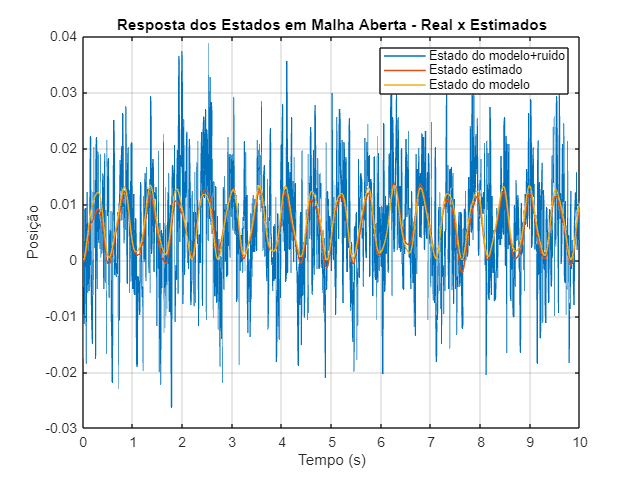

t = 0:Ts:10; % tempo de simulação

x0_fk = [0 0.1 0.1 0 0 0]; % Condições iniciais

u = zeros(size(t)); % Entrada de controle

% Simula o sistema linear original dado pela planta
[y_fk,t,x_fk] = lsim(sys_d,u,t,x0_fk); % Malha aberta
y_fk = y_fk + 0.01*randn(size(y_fk)); % Adiciona o ruido na medição

% Simula a saida dos estados estimados: 
[yest, t] = lsim(kest, [u;y_fk'],t); % Estimados
yhat = yest(:,1);
xhat = yest(:,2:end);

% Plotando
figure;
plot(t,y_fk(:,1),t,yhat,t,y_ma(:,1),'LineWidth',1)
title('Resposta dos Estados em Malha Aberta - Real x Estimados');
xlabel('Tempo (s)');
ylabel('Posição');
legend('Estado do modelo+ruido','Estado estimado','Estado do modelo');
grid on;

## Controlador LQG

% METODO : Usando a função 'rlqg'

% Matrizes de peso para o controlador LQR
Q_lqg = [10 0 0 0 0 0; % Penaliza os estados
      0 50 0 0 0 0;
      0 0 50 0 0 0;
      0 0 0 0 0 0;
      0 0 0 0 0 0;
      0 0 0 0 0 0];

R_lqg = 0.1;    % Ponderação da entrada

% Projeto do controlador LQR - Calcula os ganhos K dos estados:
K_lqg = dlqr(Ad ,Bd, Q_lqg, R_lqg)

K_lqg =           8.91        -18.91          3.72          9.00         -1.70         -0.68



% Combinação do filtro de Kalman e controlador LQR para formar o controlador LQG
rlqg = lqgreg(kest, K_lqg);



### Resposta Inicial

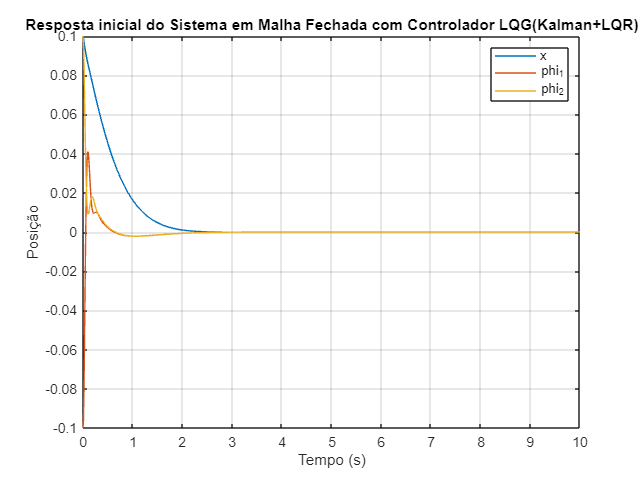

% Condições iniciais
x0_lqg = [0.1; -0.1; 0.1; 0; 0; 0]; % Exemplo de condições iniciais

% Simular a resposta Inicial do sistema com controle LQG
[y_lqg_i, t, x_lqg_i] = initial(rlqg, x0_lqg, t);

% Plotar a resposta dos estados
figure;
plot(t, x_lqg_i(:,1),t, x_lqg_i(:,2),t, x_lqg_i(:,3));
title('Resposta inicial do Sistema em Malha Fechada com Controlador LQG(Kalman+LQR)');
xlabel('Tempo (s)');
ylabel('Posição');
legend(estados{1:3});
grid on;

### Resposta ao Degrau

% Condições iniciais
x0_lqg_d = [0.1; -0.1; 0.1; 0; 0; 0]; % Exemplo de condições iniciais

% Simular a resposta Inicial do sistema com controle LQG
[y_lqg_d, t, x_lqg_d] = step(rlqg);

% Plotar a resposta dos estados
figure;
plot(t, x_lqg_d(:,1),t, x_lqg_d(:,2),t, x_lqg_d(:,3));
title('Resposta ao degrau do Sistema em Malha Fechada com Controlador LQG(Kalman+LQR)');
xlabel('Tempo (s)');
ylabel('Posição');
legend(estados{1:3});
grid on;

### Resposta ao Impulso

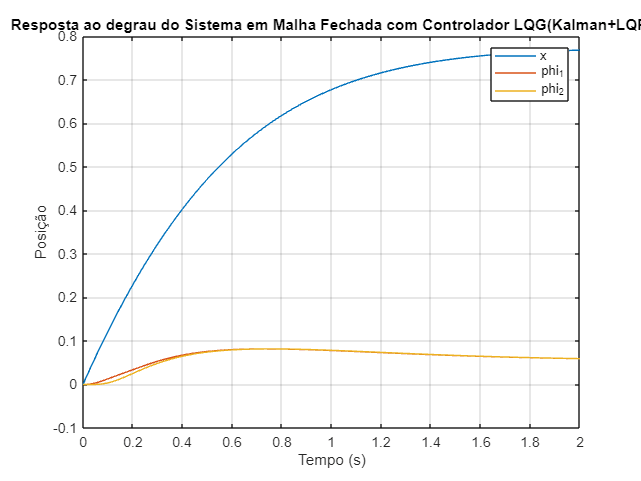

% Condições iniciais
x0_lqg_ip = [0.1; -0.1; 0.1; 0; 0; 0]; % Exemplo de condições iniciais

% Simular a resposta Inicial do sistema com controle LQG
[y_lqg_ip, t, x_lqg_ip] = impulse(rlqg);
xlim([0 2])

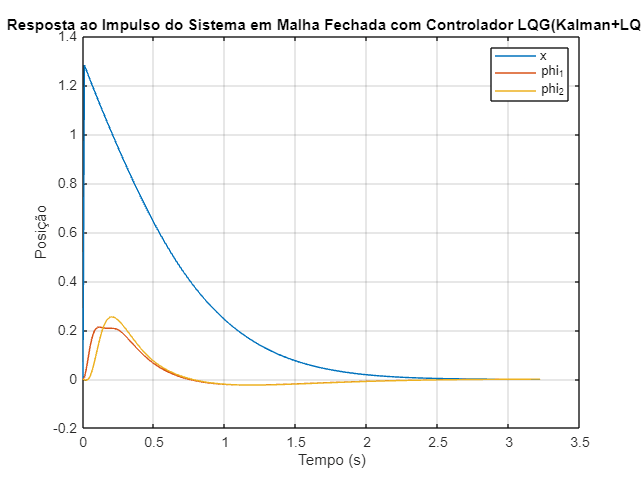

% Plotar a resposta dos estados
figure;
plot(t, x_lqg_ip(:,1),t, x_lqg_ip(:,2),t, x_lqg_ip(:,3));
title('Resposta ao Impulso do Sistema em Malha Fechada com Controlador LQG(Kalman+LQR)');
xlabel('Tempo (s)');
ylabel('Posição');
legend(estados{1:3});
grid on;

## Comparando os Controladores

### Resposta Inicial

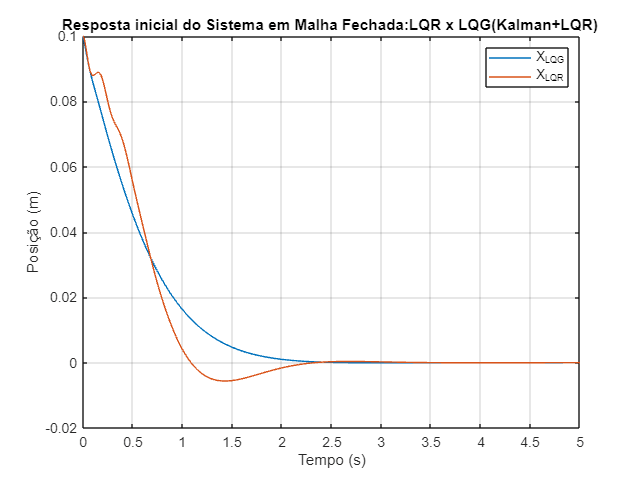

% Plotar a resposta dos estados
figure;
plot(tp, x_lqg_i(:,1),tp,y_lqr_i(:,1));
xlim([0 5]);
title('Resposta inicial do Sistema em Malha Fechada:LQR x LQG(Kalman+LQR) ');
xlabel('Tempo (s)');
ylabel('Posição (m)');
legend('X_{LQG}', 'X_{LQR}');
grid on;

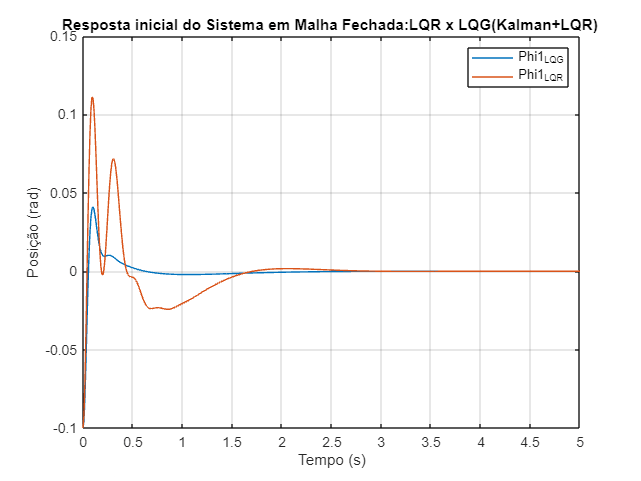



figure;
plot(tp, x_lqg_i(:,2),tp,y_lqr_i(:,2));
xlim([0 5]);
title('Resposta inicial do Sistema em Malha Fechada:LQR x LQG(Kalman+LQR) ');
xlabel('Tempo (s)');
ylabel('Posição (rad)');
legend('Phi1_{LQG}', 'Phi1_{LQR}');
grid on;

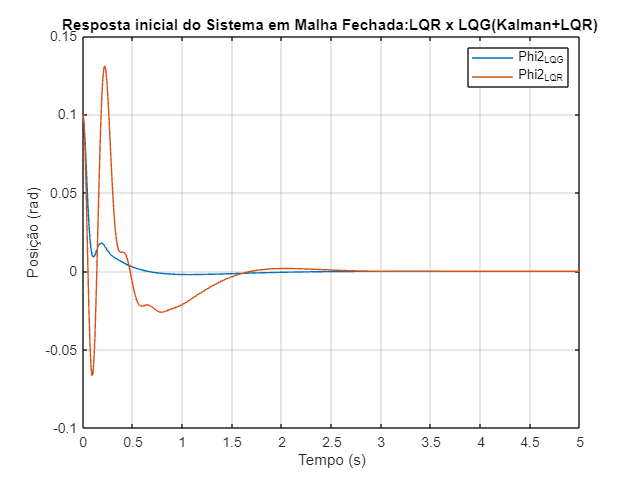



figure;
plot(tp, x_lqg_i(:,3),tp,y_lqr_i(:,3));
xlim([0 5]);
title('Resposta inicial do Sistema em Malha Fechada:LQR x LQG(Kalman+LQR) ');
xlabel('Tempo (s)');
ylabel('Posição (rad)');
legend('Phi2_{LQG}', 'Phi2_{LQR}');
grid on;